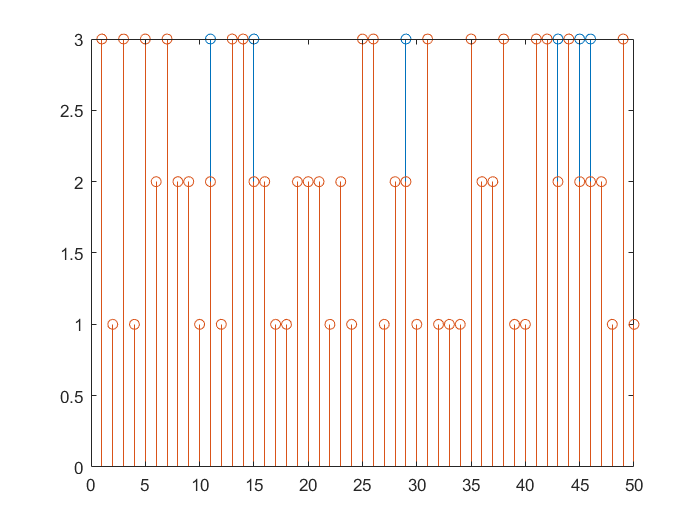

clear 
clc

% 读入数据
load iris_dataset

ind = randperm(150);
x_train = irisInputs(:,ind(1:100));
y_train = irisTargets(:,ind(1:100));

x_test = irisInputs(:,ind(101:150));
y_test = irisTargets(:,ind(101:150));

lr = 0.1;
W = rand(3,4);
delta_W = zeros(3,4);
for i = 1 : 100
    delta_W = delta_W + ...
    (y_train(:,i)-softmax(W*x_train(:,i)))*x_train(:,i)';
end

W = W + lr*delta_W;
k = 0;
while k<1000
    delta_W = zeros(3,4);
    for i = 1 : 100
        delta_W = delta_W + ...
        (y_train(:,i)-softmax(W*x_train(:,i)))*x_train(:,i)';
    end    
    W = W + lr*delta_W;
    k = k + 1;    
end

y_pred = softmax(W*x_test);
[a,b] = max(y_pred);
[aa,bb] = max(y_test);
stem(b)
hold on
stem(bb)